load('D:\Xingjian\SH_subpop\CMK\CMK_dTT_CNMFE.mat');
sh45_pca = expCell{1};
load('D:\Xingjian\SH_subpop\CMK\CMK4_dTTexp1\Cam\XZ_run\ms.mat');
sh4 = ms.FiltTraces(:, ms.cell_label==1);
load('D:\Xingjian\SH_subpop\CMK\CMK5_dTTexp1\Cam\XZ_run\ms.mat');
sh5 = ms.FiltTraces(:, ms.cell_label==1);


sh45_cnmfe = expCell{1};
sh45_cnmfe{1}.DataMatrix = sh4;
sh45_cnmfe{2}.DataMatrix = sh5;

% zscore from the beginning
sh45_cnmfe{1}.DataMatrix = zscore(sh45_cnmfe{1}.DataMatrix);
sh45_cnmfe{2}.DataMatrix = zscore(sh45_cnmfe{2}.DataMatrix);
sh45_pca{1}.DataMatrix = zscore(sh45_pca{1}.DataMatrix);
sh45_pca{2}.DataMatrix = zscore(sh45_pca{2}.DataMatrix);

% calculate baseline pcc
mlen = min(size(sh4,1), size(sh5,1));
corr(mean(sh45_pca{1}.DataMatrix(1:mlen,:),2), mean(sh45_pca{2}.DataMatrix(1:mlen,:),2))

ans = 0.2099

corr(mean(sh45_cnmfe{1}.DataMatrix(1:mlen,:),2), mean(sh45_cnmfe{2}.DataMatrix(1:mlen,:),2))

ans = 0.0725

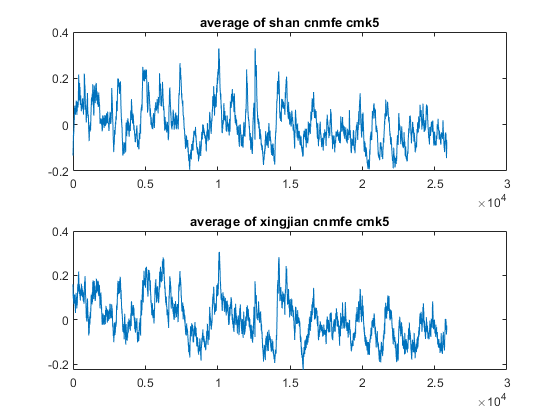

figure, subplot(2,1,1),plot(mean(sh45_pca{1}.DataMatrix(1:mlen,:),2)),title('average of shan cnmfe cmk5')
subplot(2,1,2), plot(mean(sh45_cnmfe{1}.DataMatrix(1:mlen,:),2)),title('average of xingjian cnmfe cmk5')

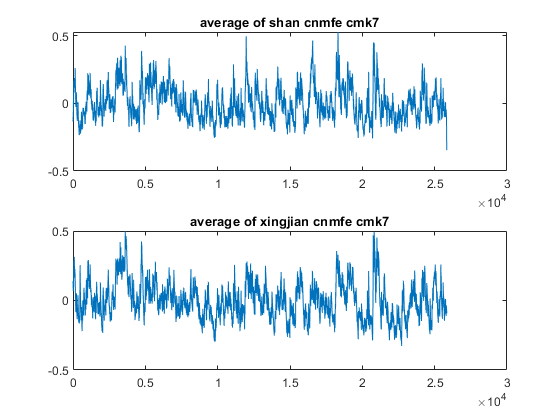


figure, subplot(2,1,1),plot(mean(sh45_pca{2}.DataMatrix(1:mlen,:),2)),title('average of shan cnmfe cmk7')
subplot(2,1,2), plot(mean(sh45_cnmfe{2}.DataMatrix(1:mlen,:),2)),title('average of xingjian cnmfe cmk7')

corr(mean(sh45_pca{1}.DataMatrix(1:mlen,:),2),mean(sh45_cnmfe{1}.DataMatrix(1:mlen,:),2))

ans = 0.8448

corr(mean(sh45_pca{2}.DataMatrix(1:mlen,:),2),mean(sh45_cnmfe{2}.DataMatrix(1:mlen,:),2))

ans = 0.8112

corr(mean(sh45_pca{2}.DataMatrix(1:mlen,:),2)-mean(sh45_cnmfe{2}.DataMatrix(1:mlen,:),2),mean(sh45_pca{1}.DataMatrix(1:mlen,:),2)-mean(sh45_cnmfe{1}.DataMatrix(1:mlen,:),2))

ans = -0.0725

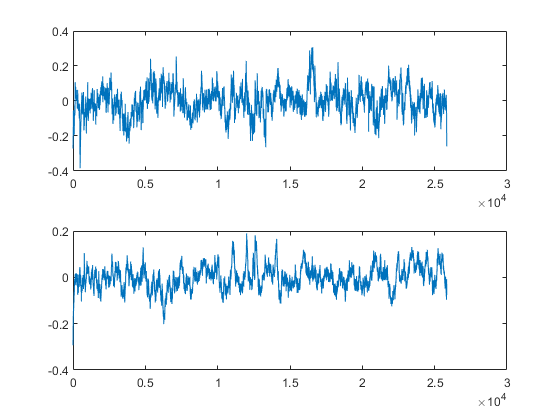

figure, subplot(2,1,1), plot(mean(sh45_pca{2}.DataMatrix(1:mlen,:),2)-mean(sh45_cnmfe{2}.DataMatrix(1:mlen,:),2));
subplot(2,1,2),plot(mean(sh45_pca{1}.DataMatrix(1:mlen,:),2)-mean(sh45_cnmfe{1}.DataMatrix(1:mlen,:),2))

% find the corresponding cells
cor_mat = zeros(size(sh45_cnmfe{1}.DataMatrix,2), size(sh45_pca{1}.DataMatrix,2));
% find sh4
for i = 1:size(sh45_cnmfe{1}.DataMatrix,2)
    for j = 1:size(sh45_pca{1}.DataMatrix,2)
        cor_mat(i,j) = corr(sh45_cnmfe{1}.DataMatrix(1:mlen,i), sh45_pca{1}.DataMatrix(1:mlen,j)); 
    end
end
% sort PCA with CNMFE order
[~,I] = max(cor_mat,[], 2);
sh45_pca_sorted = sh45_pca;
sh45_pca_sorted{1}.DataMatrix = sh45_pca_sorted{1}.DataMatrix(:,I);

% find the corresponding cells
cor_mat2 = zeros(size(sh45_cnmfe{2}.DataMatrix,2), size(sh45_pca{2}.DataMatrix,2));
% find sh5
for i = 1:size(sh45_cnmfe{2}.DataMatrix,2)
    for j = 1:size(sh45_pca{2}.DataMatrix,2)
        cor_mat2(i,j) = corr(sh45_cnmfe{2}.DataMatrix(1:mlen,i), sh45_pca{2}.DataMatrix(1:mlen,j)); 
    end
end
% sort PCA with CNMFE order
[~,I] = max(cor_mat2,[], 2);
sh45_pca_sorted{2}.DataMatrix = sh45_pca_sorted{2}.DataMatrix(:,I);

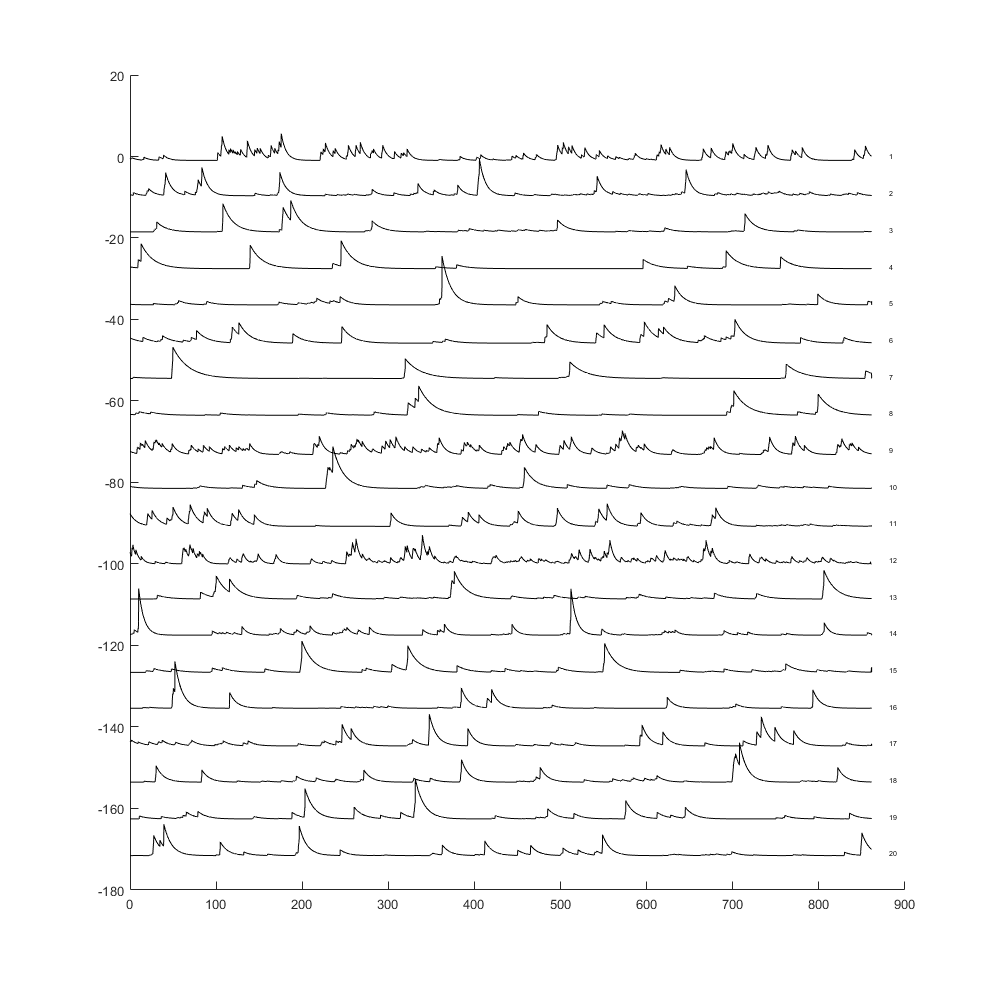

% plot top 20 cells
PlotSelectedCells(sh45_pca_sorted{1}, 1:20);

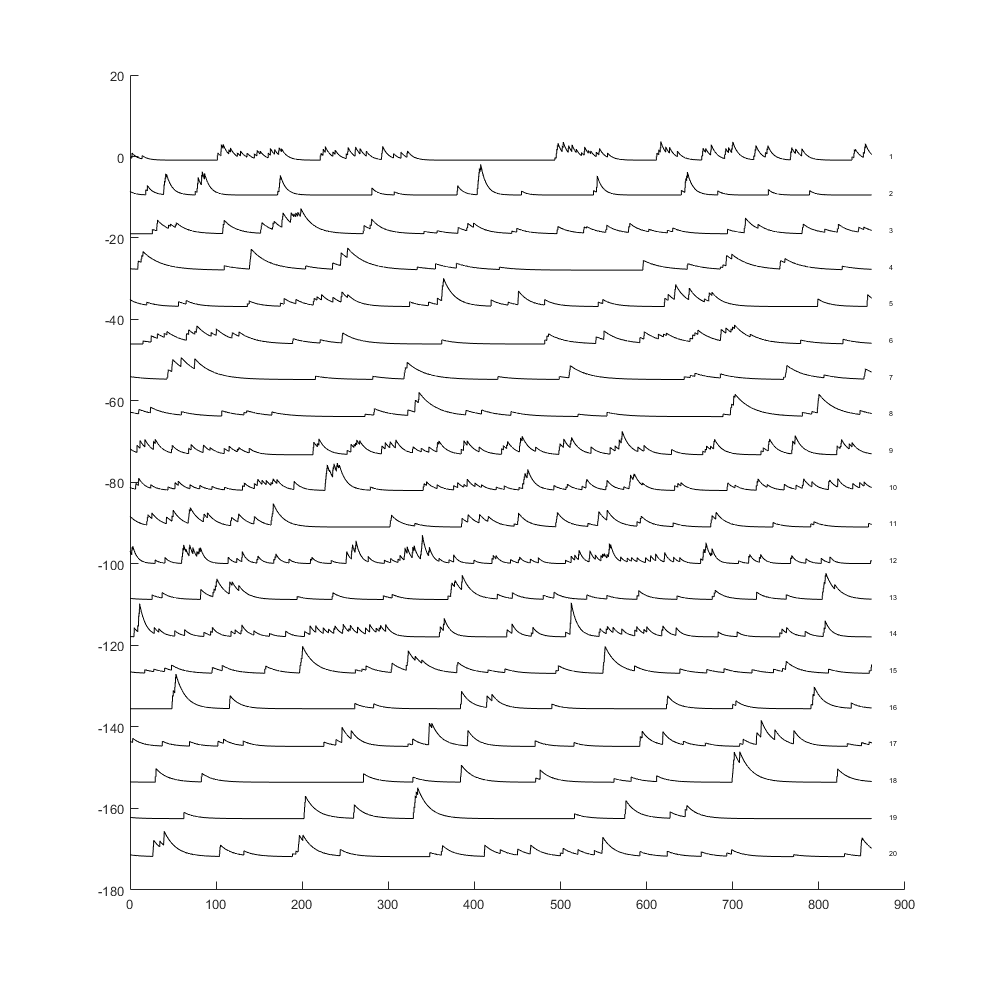

PlotSelectedCells(sh45_cnmfe{1},1:20);

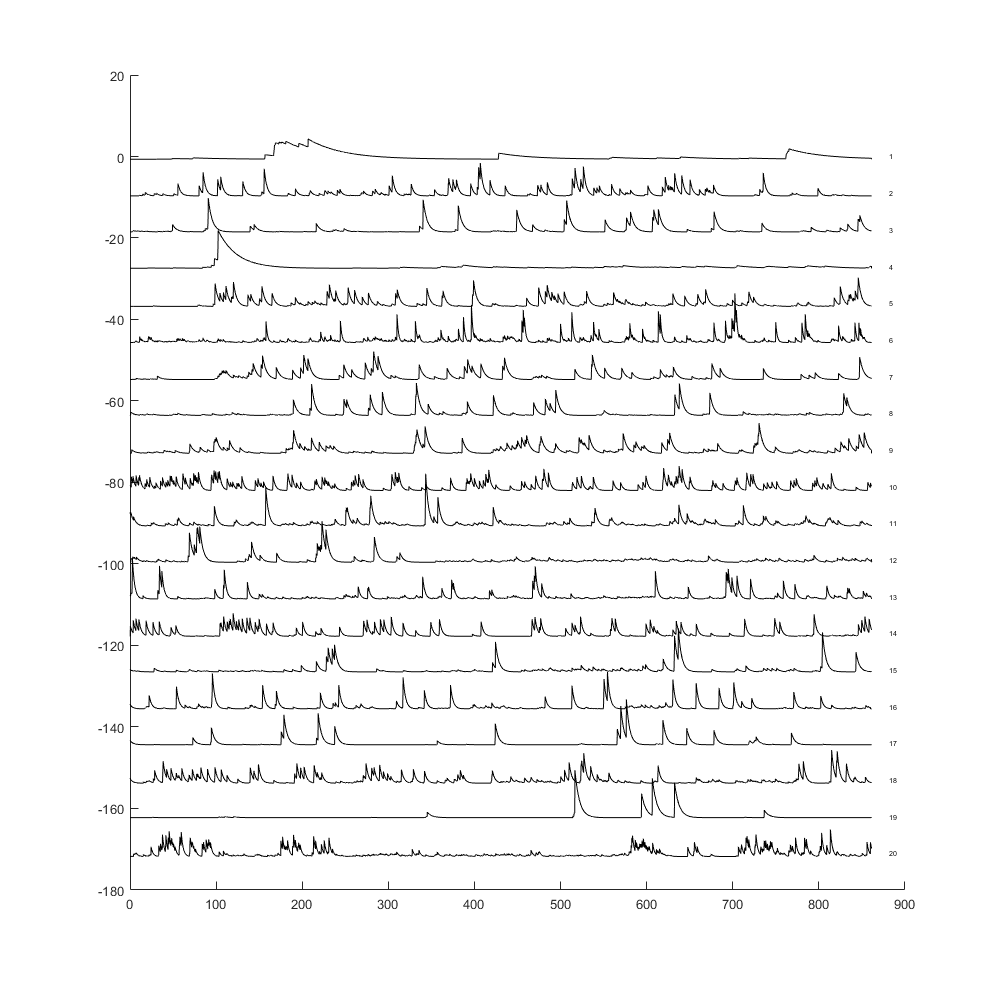

PlotSelectedCells(sh45_pca_sorted{2},1:20);

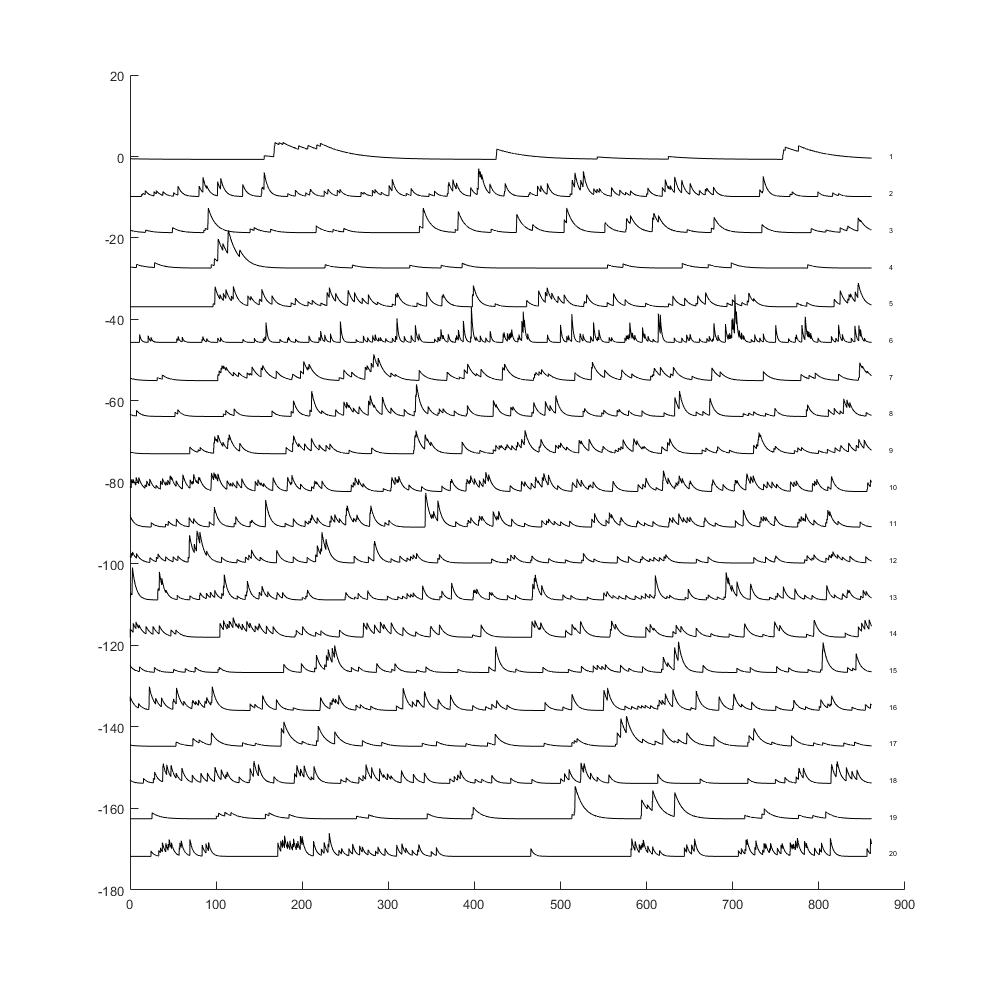

PlotSelectedCells(sh45_cnmfe{2},1:20);

% calculate pcc
fprintf('pca:')

pca:

corr(mean(sh45_pca_sorted{1}.DataMatrix(1:mlen,1:20),2),mean(sh45_pca_sorted{2}.DataMatrix(1:mlen,1:20),2))

ans = 0.0165

fprintf('cnmfe')

cnmfe

corr(mean(sh45_cnmfe{1}.DataMatrix(1:mlen,1:20),2), mean(sh45_cnmfe{2}.DataMatrix(1:mlen,1:20),2))

ans = 0.0130

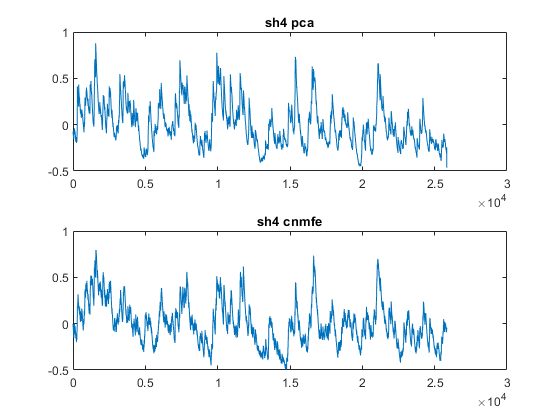

figure, 
subplot(2,1,1), plot(mean(sh45_pca_sorted{1}.DataMatrix(:,1:20),2)), title('sh4 pca');
subplot(2,1,2), plot(mean(sh45_cnmfe{1}.DataMatrix(1:mlen,1:20),2)), title('sh4 cnmfe');

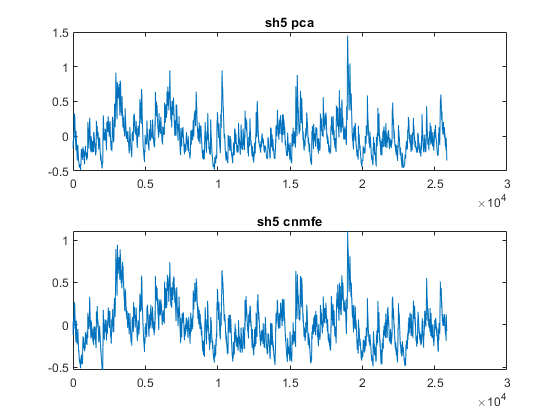

figure,
subplot(2,1,1), plot(mean(sh45_pca_sorted{2}.DataMatrix(:,1:20),2)), title('sh5 pca');
subplot(2,1,2),plot(mean(sh45_cnmfe{2}.DataMatrix(1:mlen,1:20),2)), title('sh5 cnmfe');

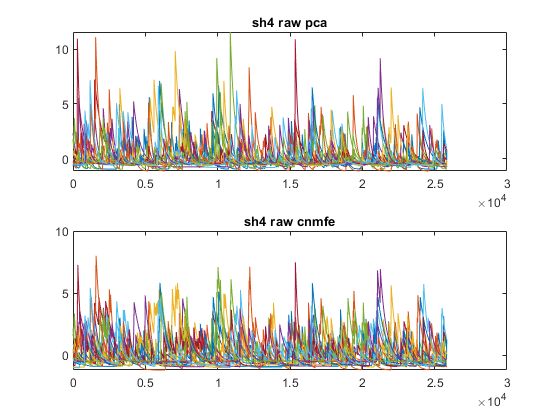

% raw signal comparison
figure, subplot(2,1,1), plot(sh45_pca_sorted{1}.DataMatrix(:,1:20)), title('sh4 raw pca');
subplot(2,1,2), plot(sh45_cnmfe{1}.DataMatrix(:,1:20)), title('sh4 raw cnmfe');

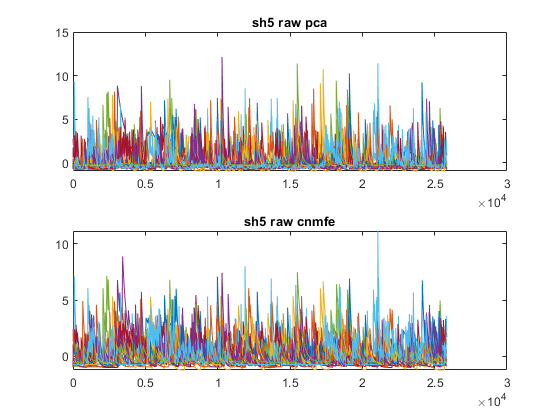

figure, subplot(2,1,1), plot(sh45_pca_sorted{2}.DataMatrix(:,1:20)), title('sh5 raw pca');
subplot(2,1,2), plot(sh45_cnmfe{2}.DataMatrix(:,1:20)), title('sh5 raw cnmfe');

% Looking at raw figure, notice that cell1 of sh5  stands out in PCA
% remove this cell, recalculate pcc
fprintf('pca:')

pca:

corr(mean(sh45_pca_sorted{1}.DataMatrix(:,1:20),2),mean(sh45_pca_sorted{2}.DataMatrix(:,2:20),2))

ans = 0.1351

fprintf('cnmfe')

cnmfe

corr(mean(sh45_cnmfe{1}.DataMatrix(1:mlen,1:20),2), mean(sh45_cnmfe{2}.DataMatrix(1:mlen,2:20),2))

ans = 0.0414

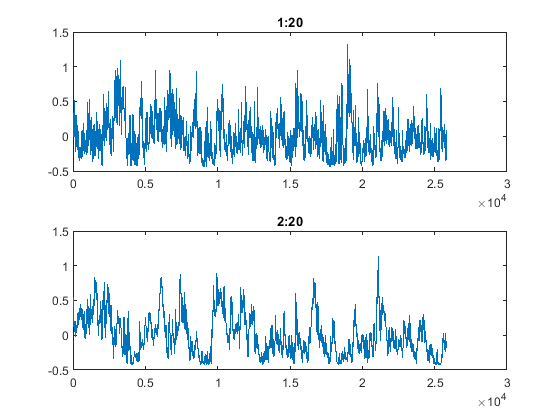


figure, subplot(2,1,1),plot(mean(sh45_pca_sorted{2}.DataMatrix(:,1:20),2)), title("1:20");
subplot(2,1,2),plot(mean(sh45_pca_sorted{1}.DataMatrix(:,2:20),2)), title('2:20');

% remove all cell peak > thr in PCA
thr = Inf;
pca_sh4_idx = find(max(sh45_pca{1}.DataMatrix,[], 1) < thr);
pca_sh5_idx = find(max(sh45_pca{2}.DataMatrix,[], 1) < thr);
corr(mean(sh45_pca{1}.DataMatrix(:,pca_sh4_idx),2), mean(sh45_pca{2}.DataMatrix(:,pca_sh5_idx),2))

ans = 0.4898

% conclusion: FFT video is the difference maker. filtering out small
% fluctuations (noise, background fluorescence and small signals) boost the
% sig-noise ratio, making the overall trend more prominent. When average
% over a population of neurons, the signal of a small subset of neurons
% will basically be averaged to the level of noise, so a clean baseline
% makes a huge impact. 
